# Explore the dynamics of a 2-dof NON-planar Robotic manipulator

In this example we're going to derive and then implement the equations of motion for a 2-dof non-planar robotic manipulator. Specifically we're going to:

- Derive the equations of motion using's Lagrange's method

The system that we're going to explore is shown below.  At each joint we have:

- $\tau_m$   :     Actuation torques (eg: by electric motors)

- $b.\dot{\theta}$  :    Viscous damping torques

   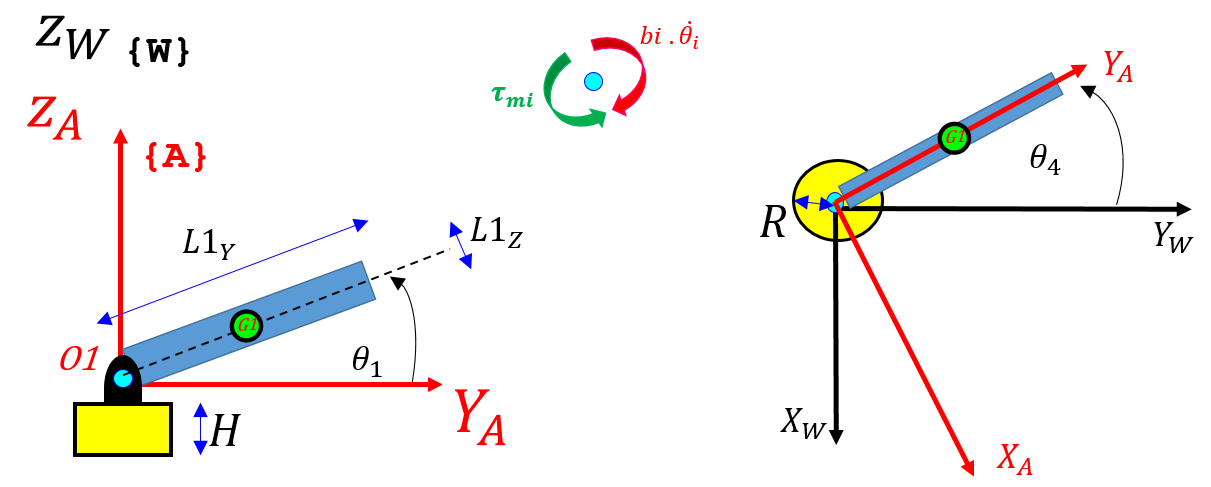                

`Bradley Horton : 09-Mar-2017, bradley.horton@mathworks.com.au`           

Here's a short video showing the type of machine that we're going to derive the equations of motion for - note the 2 degrees of freedom that the machine has:

disp('CLICK ME to PLAY a MOVIE')

# **STAGE 1:** symbolic derivation of system equations

## Euler-Lagrange equations of motion:

The Euler-Lagrange formula will be used to derive the equations of motion for our robotic manipulator, and it has the form:

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

**Note** : 

- For our system, we will choose  *q = {*$\theta_1 \thinspace,  \theta_4$*}* 

- This is a 2 degree of freedom system, and as such there are two 2nd order ODEs that can be derived.

## Defining Model parameters and geometry:

                  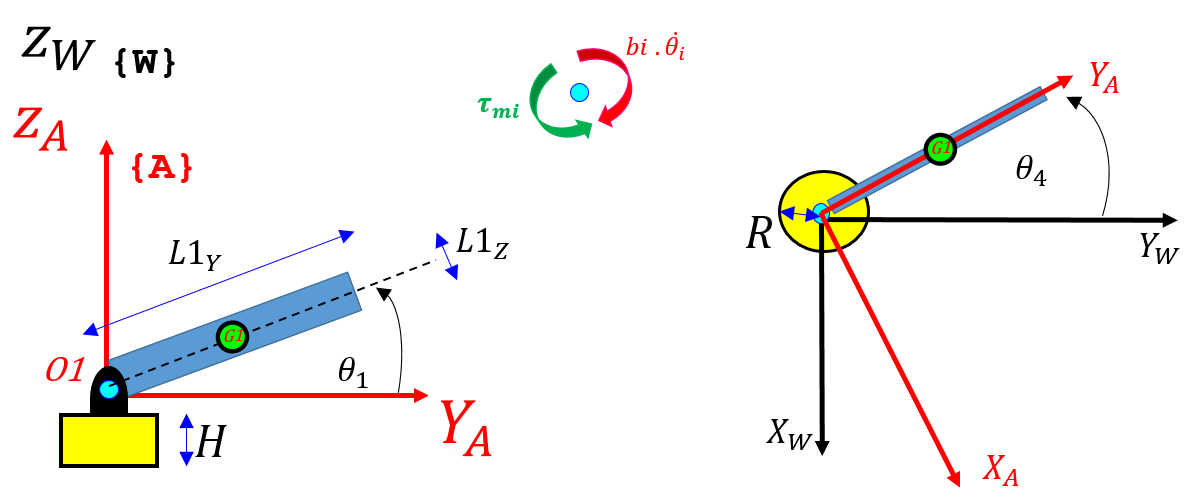       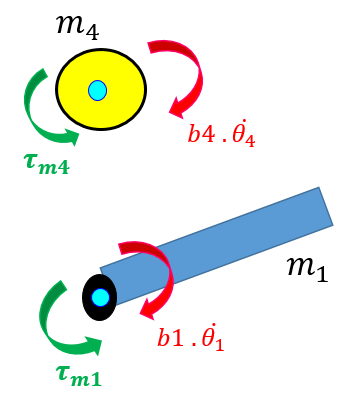   

Here are some model parameters:

syms    m1_s        m4_s  % masses
syms    b1_s        b4_s  % damping
syms taum1_s     taum4_s  % motor torques
syms     g_s              % gravity 

syms L1X_s L1Y_s  L1Z_s  % lengths for LINK #1
syms H4_s  R4_s          % lengths for LINK #4 (aka TURNTABLE)

Here are the angles that describe the pose for our machine.  These 2 angles are also the generalised co-ordinates that we'll use with Lagrange's equation:

syms t  theta1(t)     theta4(t)   

## Defining component INERTIAs:

The manipulator is made up of a rectangular prism lasbelled as LINK-1 - which forms the robotic "arm".  The robot  also has LINK-4 which is the cylindrical base or "turntable".  The inertias for these fundamental shapes can be computed about a local body frame positioned at their center of mass (CoM):

   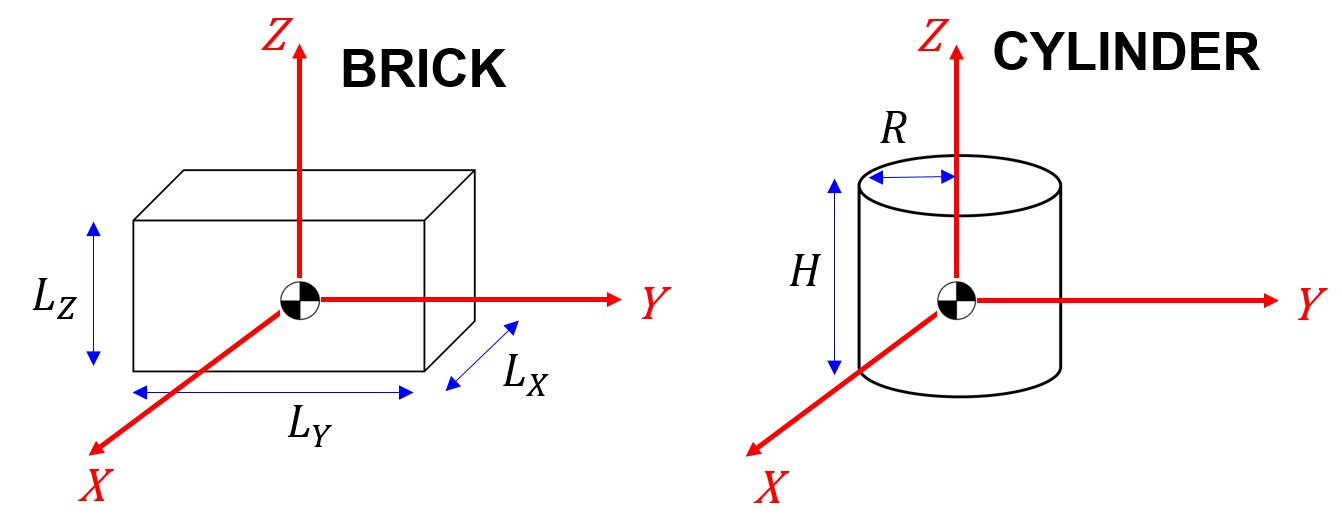

So let's define the INERTIA matrices for these components about their body fixed **center of mass** frames:

I_brick = @(Lx,Ly,Lz,m)...
    ( [m*(Ly^2 + Lz^2)/12,  0,                   0; ...
                        0,  m*(Lx^2 + Lz^2)/12,  0; ...
                        0,  0,                   m*(Lx^2 + Ly^2)/12;] ); 

I_cyl = @(H,R,m)...
    ( [m*(H^2 + 3*R^2)/12,  0,                   0; ...
                        0,  m*(H^2 + 3*R^2)/12,  0; ...
                        0,  0,                   m*(R^2)/2;] ); 

So the INERTIA matrices for our 2 bodies are:

I1_s = I_brick(L1X_s, L1Y_s, L1Z_s, m1_s);
I4_s = I_cyl(H4_s,  R4_s, m4_s);

As a concrete example, here's what the inertia matrix for Link 1, looks like:

I1_s

## Define Center of mass positions and TRANSLATIONAL velocities for ARM link:

In the diagrams below, we've defined the inertial(fixed) World co-ordinate frame to be at the pivot point between links 1 and 4 - this {W}-frame is fixed in space ... it does NOT move.  We've also defined a frame called the {A-frame} - the {A}-frame shares the same origin as the {W}-frame, however the {A}-frame may rotate about the common $^WZ$and $^AZ$axes.  We've also attached **body fixed** co-ordinate frames to the center of mass(CoM) of each link.  So note the following frames:

- *{W}-frame is our INERTIAL frame*

- *{A}-frame* rotates with robot about the common $^WZ$and $^AZ$axes

- *{B1}-frame* is attached to CoM of Link 1

           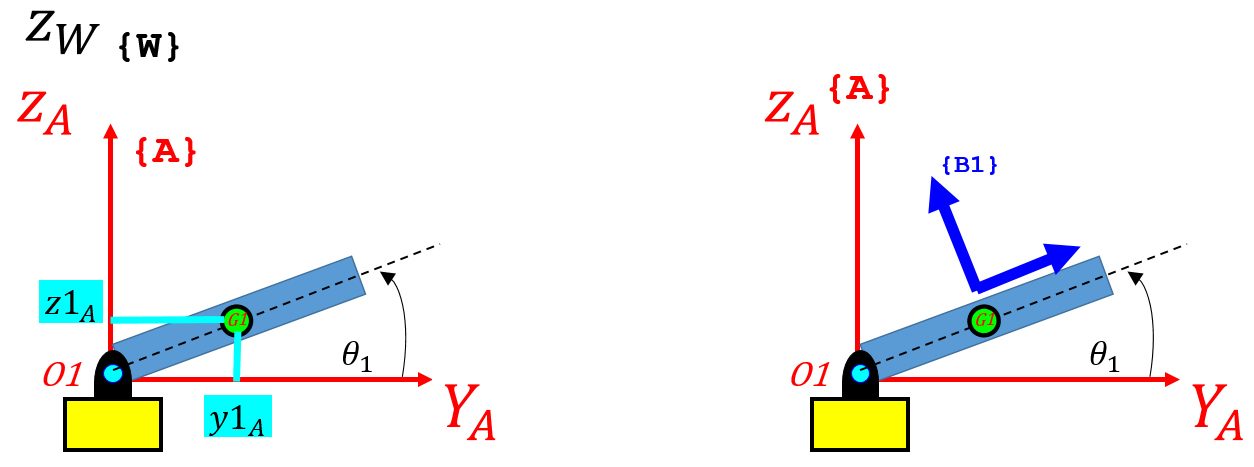   

First, let's define the x,y,z position of the **centre of mass** (CoM) for LINK-1 - and we'll define these positions in terms of the {A}-Frame.  And after we've done this, we'll convert the CoM positions to our inertial {W}-frame, and then we can differentiate to get translational velocities: 

**Consider LINK_1:** *- where is the CoM relative to the {A}-Frame  *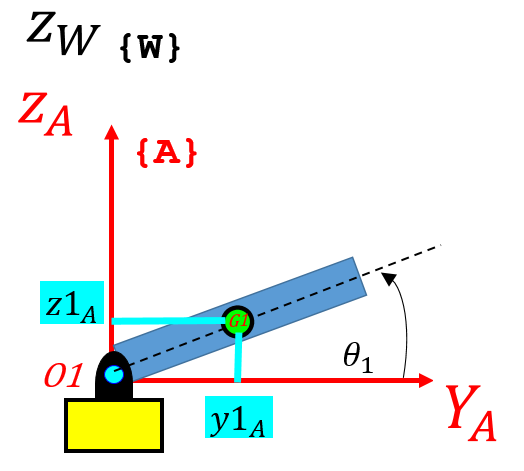

AF_pos_G1      = sym([0;0;0]);
AF_pos_G1(2,1) = (L1Y_s/2)*cos(theta1(t));  % y1A
AF_pos_G1(3,1) = (L1Y_s/2)*sin(theta1(t));  % z1A

We can now convert these {A}-Frame co-ordinates into their corresponding {W}-frame co-ordinates using the following transformation $^Wr = {^WR}_A \thinspace . \thinspace ^Ar$:

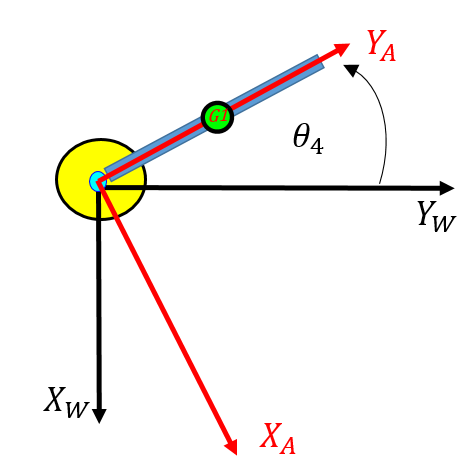   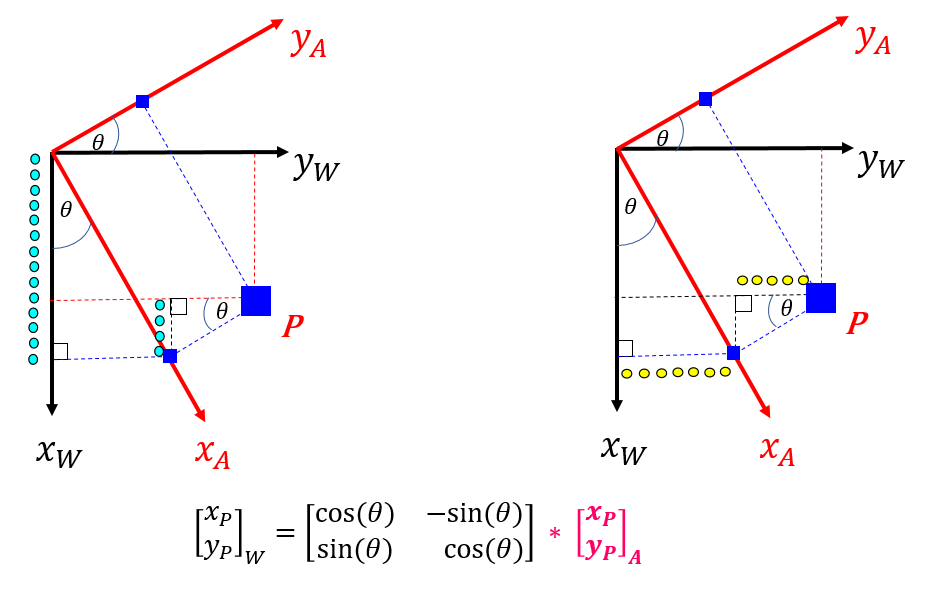

wRa = [ cos(theta4(t)),  -sin(theta4(t)),   0;
        sin(theta4(t)),   cos(theta4(t)),   0;
                     0,                0,   1 ]

So our {W}-Frame position co-ordinates for the LINK-1 center of mass is:

WF_pos_G1 = wRa * AF_pos_G1;                 

As a concrete example, here's the {x,y,z} co-ordinate of the centre of mass for LINK-1, expressed in the {W}-frame:

WF_pos_G1

Now calculate our ***translational velocities*** for LINK-1 and express in terms of the {W}-Frame:

WF_tran_vel_G1 = diff( WF_pos_G1, t);  

As a concrete example, here's what the translational velocity vector $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack$ looks like for the center of mass of Link #1,  expressed in components of the INERTIAL {W}-frame:

WF_tran_vel_G1

## Define ROTATIONAL velocities for all bodies:

            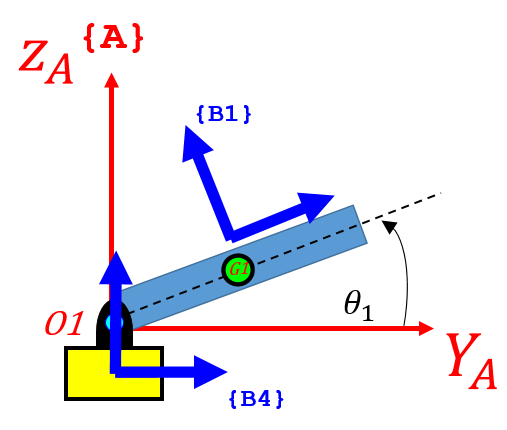           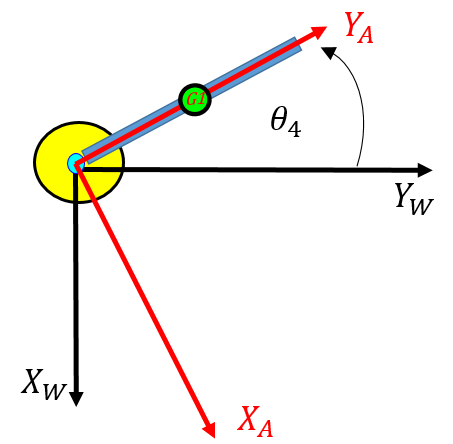  

Next we're going to define the rotational velocities for our 2 bodies. And we're going to express these rotational velocities in components of the local centre of mass BODY fixed frames attached to each body - this is a natural approach because a body fixed frame means our inertias stay constant relative to that frame.  The angular velocities that we'll define are:

- $^{B1}\omega_1 :$ is the angular velocity of LINK 1, expressed in components of the {B1}-Frame

- $^{B4}\omega_4 :$ is the angular velocity of LINK 4, expressed in components of the {B4}-Frame

Note also, we can use the following transformation matrix, to convert an {A}-Frame vector into it's {B}-Frame components - we'll use this to convert our TURNTABLE angular velocity into components of the LINK body fixed frames. WHY? - the total angular velocity of LINK 1 is a vector sum which will include the contribution of the turntable angular velocity ie: 

- 
$${}^{B1}_{\text{ }}{\omega }^{\text{ }}_1=\text{ }{}^{B1}_{\text{ }}R^{\text{ }}_A\ldotp {}^A_{\text{ }}{\omega }^{\text{ }}_A\text{   }

 \quad +  \quad

\text{   }{}^{B1}_{\text{ }}{\omega }^{\text{ }}_{1\mid A}$$
      

where:   ${}^{\text{B1}}_{\text{ }}{\omega }^{\text{ }}_{1\text{∣}A}$ is the angular velocity of LINK-1relative to the {A}-frame.

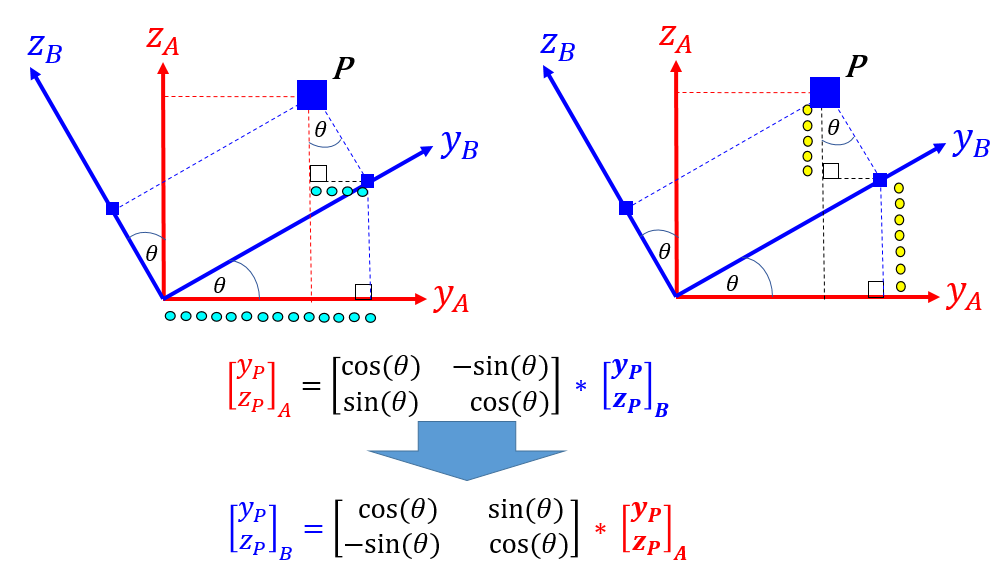

*NOTE:   in the code below, we've created "function handle" variables to parameterise the rotation matrix *$^BR_A$* .*

bRa = @(th) [       1,          0,         0;
                    0,    cos(th),   sin(th);
                    0,   -sin(th),   cos(th); ];

OK, so let's do it.  First let's define the angular velocity of the turntable (ie Link #4) ... which is the same thing as our {A}-frame angular velocity: 

BF_rot_vel_B4 = [0;0; diff(theta4(t))];
AF_w          = [0;0; diff(theta4(t)) ];

Next, let's define the angular velocity for LINK-1, ie:   ${}^{B1}_{\text{ }}{\omega }^{\text{ }}_1=\text{ }{}^{B1}_{\text{ }}R^{\text{ }}_A\ldotp {}^A_{\text{ }}{\omega }^{\text{ }}_A\text{   }

 \quad +  \quad

\text{   }{}^{B1}_{\text{ }}{\omega }^{\text{ }}_{1\mid A}$ 

th1           = theta1(t)                             ;
BF_rot_vel_B1 = bRa(th1)*AF_w  +  [diff(th1)   ; 0; 0];

As a concrete example, here's what the angular velocity vector $^{B1}\omega_1 =$$\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$, looks like, for LINK-1 and expressed in components of the body fixed {B1}-frame:

BF_rot_vel_B1

## Define the system KINETIC energy:

Next we'll use our previously derived expressions for body velocities and use them to define the "system" Kinetic Energy for our machine.  Because we've attached our BODY frames to the **centre of masses** of every link, the kinetic energy for the $i^{th}$ link can be stated as:


$${\text{KE}}_i =\text{ }\frac{1}{2}{v_{{\text{cm}}_i }^T {\ldotp m}_i } {\text{ }\ldotp v}_{{\text{cm}}_i } \text{ }\text{ }\text{ }+\text{    }\text{ }\frac{1}{2}\ldotp \omega_{B_i }^T \ldotp \left\lbrack I_{{cm}_i } \right\rbrack \ldotp \omega_{B_i }$$


The total system kinetic energy is then just the sum of the "*N*" individual link kinetic energies, ie:


$${KE}_{system} =\text{ }\sum_{i=1}^{N} {KE}_i$$


Our TRANSLATIONAL kinetic energy is:

KE_trans = 0.5*m1_s * (WF_tran_vel_G1.') *  WF_tran_vel_G1   ;

Our ROTATIONAL kinetic energy is:

KE_rot   = 0.5 * (BF_rot_vel_B1.') * I1_s *  BF_rot_vel_B1  + ...
           0.5 * (BF_rot_vel_B4.') * I4_s *  BF_rot_vel_B4;           

So our total system kinetic energy is:

KE = KE_trans + KE_rot;      

## Define the system POTENTIAL energy:

Similarly we can define our "system" Potential Energy:

Our system Potential energy is:

PE = g_s*( m1_s*WF_pos_G1(3)   );

## Define the system Lagrangian:

Next define our system Lagrangian:

L_ORIGINAL = KE - PE;

***IFFF*** you really wanted to see what the terms inside the Lagrangian looked like (are you sure?) ... then we could echo them:

the_list_of_terms_making_up_L = children(L_ORIGINAL);
the_list_of_terms_making_up_L(:)

## Getting ready to Apply Lagrange's equation:

Before we calculate Lagrange's equation:

-  $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

we'll first create some variables that define our generalised co-ordinates (and their rates, accels).  I'm going to use 2 sets of these generalised co-ordinates:

- the **ACTUAL** set of symbols are our "proper" set of symbols

- the **HOLDER** set are for easier expression manipulation (these are purely for convenience)

To be clear what we're talking about here, sometimes we might write an axpression using symbols like this:


$$m.\frac{d^2x(t)}{dt^2} + c. \frac{dx(t)}{dt} + k \thinspace.\thinspace x(t) = F$$


and sometimes we might like to write the exact SAME expression like this:


$$m.X\_DD + c . X\_D + k . X = F$$


syms        TH1_s         TH4_s     TH1D_s   TH1DD_s  TH4D_s   TH4DD_s 

tmp_mat        =   [     theta1     ,  TH1_s    ;
                    diff(theta1,t)  ,  TH1D_s   ;
                    diff(theta1,t,2),  TH1DD_s  ;
                         theta4     ,  TH4_s    ;
                    diff(theta4,t)  ,  TH4D_s   ;
                    diff(theta4,t,2),  TH4DD_s  ;  ]; 
                
tmp_mat         = formula( tmp_mat       );             
actual_list_SYM =          tmp_mat(:,1)  ;
holder_list_SYM =          tmp_mat(:,2)   ;

You can think of these 2 sets of symbols as:


$$\matrix{
  \theta_1(t) & \dot{\theta_1}(t) & \ddot{\theta_1} &\theta_4(t) & \dot{\theta_4}(t) & \ddot{\theta_4}(t)\cr
\downarrow & \downarrow & \downarrow & \downarrow & \downarrow & \downarrow \cr
TH1\_s & TH1D\_s  & TH1DD\_s  & 
TH4\_s & TH4D\_s  & TH4DD\_s
}$$


# **Define the Generalised forces:**

Next we need to calculate our Generalised forces.  Recall the formula for the generalised forces acting on the system:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

For our system, here are all of the NON-conservative forces:

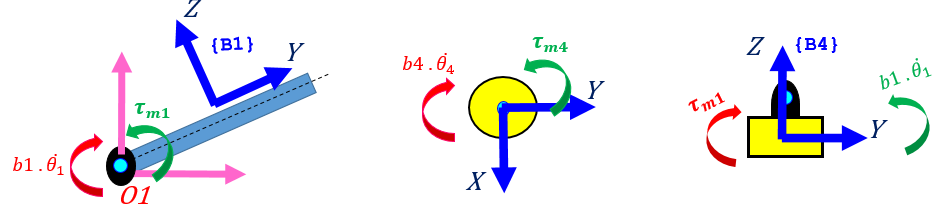

Define some "convenience" things:

th1dot     = formula( diff(theta1, t)  );
th4dot     = formula( diff(theta4, t)  );

The columns in the matrix below, represent all of the NON-conservative torque vectors:

the_tau_mat = [     (taum1_s),    (-b1_s*th1dot),              0,                 0,   (b1_s*th1dot - taum1_s);
                            0,                 0,              0,                 0,                         0;
                            0,                 0,      (taum4_s),    (-b4_s*th4dot),                         0;    ]; 
       
the_w_mat   = [ BF_rot_vel_B1,     BF_rot_vel_B1,  BF_rot_vel_B4,     BF_rot_vel_B4,             BF_rot_vel_B4     ];

And change the symbols in these expressions such that they are only using the HOLDER set of symbols:

the_tau_mat = subs(the_tau_mat, actual_list_SYM, holder_list_SYM ); 
the_w_mat   = subs(the_w_mat,   actual_list_SYM, holder_list_SYM ); 

So for $\theta_1$, we have:  


$$Q_1 = 
\pmatrix{\tau_{m1} \cr 0 \cr 0}.
 \thinspace \frac{\partial \thinspace \vec{^{B1}\omega_1}}{\partial \dot{\theta_1}
}
\quad + \quad
\pmatrix{-b_1.\theta_1 \cr 0 \cr 0}.
 \thinspace \frac{\partial \thinspace \vec{^{B1}\omega_1}}{\partial \dot{\theta_1}
}
\quad + \quad
\pmatrix{ 0 \cr 0 \cr \tau_{m4}}.
 \thinspace \frac{\partial \thinspace \vec{^{B4}\omega_4}}{\partial \dot{\theta_1}
}
\quad + \quad
\pmatrix{ 0 \cr 0 \cr -b_4.\dot{\theta_4}}.
 \thinspace \frac{\partial \thinspace \vec{^{B4}\omega_4}}{\partial \dot{\theta_1}
}
\quad + \quad
\pmatrix{ b_1.\theta_1 - \tau_{m1} \cr 0 \cr 0}.
 \thinspace \frac{\partial \thinspace \vec{^{B4}\omega_4}}{\partial \dot{\theta_1}
}$$


the_qdot_sym = TH1D_s;
the_Q        = 0;

for jj=1:size(the_tau_mat,2) 
   the_tau_col  = the_tau_mat(:,jj);
   the_w_col    =   the_w_mat(:,jj);
   the_dwdq_col = diff(the_w_col, the_qdot_sym);
   % now do the DOT product
   this_Q       = sum( the_tau_col .* the_dwdq_col   );
   % accumulate 
   the_Q = the_Q + this_Q;
end % jj

THE_Q1 = the_Q;

So for $\theta_4$, we have:  


$$Q_4 = 
\pmatrix{\tau_{m1} \cr 0 \cr 0}.
 \thinspace \frac{\partial \thinspace \vec{^{B1}\omega_1}}{\partial \dot{\theta_4}
}
\quad + \quad
\pmatrix{-b_1.\theta_1 \cr 0 \cr 0}.
 \thinspace \frac{\partial \thinspace \vec{^{B1}\omega_1}}{\partial \dot{\theta_4}
}
\quad + \quad
\pmatrix{ 0 \cr 0 \cr \tau_{m4}}.
 \thinspace \frac{\partial \thinspace \vec{^{B4}\omega_4}}{\partial \dot{\theta_4}
}
\quad + \quad
\pmatrix{ 0 \cr 0 \cr -b_4.\dot{\theta_4}}.
 \thinspace \frac{\partial \thinspace \vec{^{B4}\omega_4}}{\partial \dot{\theta_4}
}
\quad + \quad
\pmatrix{ b_1.\theta_1 - \tau_{m1} \cr 0 \cr 0}.
 \thinspace \frac{\partial \thinspace \vec{^{B4}\omega_4}}{\partial \dot{\theta_4}
}$$


the_qdot_sym = TH4D_s;
the_Q        = 0;

for jj=1:size(the_tau_mat,2) 
   the_tau_col  = the_tau_mat(:,jj);
   the_w_col    =   the_w_mat(:,jj);
   the_dwdq_col = diff(the_w_col, the_qdot_sym);
   % now do the DOT product
   this_Q       = sum( the_tau_col .* the_dwdq_col   );
   % accumulate 
   the_Q = the_Q + this_Q;
end % jj

THE_Q4 = the_Q;

So what does the $\theta_1$ Generalised Force look like ?

THE_Q1

So what does the $\theta_4$ Generalised Force look like ?

THE_Q4

# **Apply Lagrange's equation:**

So let's now apply Lagrange's equation:

-  $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

## Derive the $\theta_1$ EOM:      $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_1} - \frac{\partial L}{\partial \theta_1} = Q_1 $     

Recall our variable mapping:


$$\matrix{
  \theta_1(t) & \dot{\theta_1}(t) & \ddot{\theta_1} &\theta_4(t) & \dot{\theta_4}(t) & \ddot{\theta_4}(t)\cr
\downarrow & \downarrow & \downarrow & \downarrow & \downarrow & \downarrow \cr
TH1\_s & TH1D\_s  & TH1DD\_s  & 
TH4\_s & TH4D\_s  & TH4DD\_s
}$$


L = subs(L_ORIGINAL, actual_list_SYM, holder_list_SYM ); 

Now let's do this part:    $\frac{\partial L}{\partial \dot{\theta_1}} $   

dLdq1p = diff(L, TH1D_s);
dLdq1p = subs(dLdq1p,  holder_list_SYM,  actual_list_SYM );    

Next, let's take the derivative w.r.t time:     $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta_1}}  $ 

der_dt_of_dLdq1p = diff(dLdq1p, t);

Next, let's do this part:   $\frac{\partial L}{\partial \theta_1} $  

dLdq1 = diff(L, TH1_s);
dLdq1 = subs(dLdq1,  holder_list_SYM,  actual_list_SYM);

So our first equation of motion is:


$$\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_1} - \frac{\partial L}{\partial \theta_1} = Q_1 $$


EOM_TH1     = simplify(der_dt_of_dLdq1p - dLdq1) == THE_Q1;

So what does it look like ? - note the system coupling (ie: presense of $\ddot{\theta}_1$ and $\ddot{\theta}_4
$)

simplify(EOM_TH1)

## Derive the $\theta_4$ EOM:      $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_4} - \frac{\partial L}{\partial \theta_4} = Q_4 $     

Recall our variable mapping:


$$\matrix{
  \theta_1(t) & \dot{\theta_1}(t) & \ddot{\theta_1} &\theta_4(t) & \dot{\theta_4}(t) & \ddot{\theta_4}(t)\cr
\downarrow & \downarrow & \downarrow & \downarrow & \downarrow & \downarrow \cr
TH1\_s & TH1D\_s  & TH1DD\_s  & 
TH4\_s & TH4D\_s  & TH4DD\_s
}$$


L = subs(L_ORIGINAL, actual_list_SYM, holder_list_SYM ); 

Now let's do this part:    $\frac{\partial L}{\partial \dot{\theta_4}} $   

dLdq1p = diff(L, TH4D_s);
dLdq1p = subs(dLdq1p,  holder_list_SYM,  actual_list_SYM );    

Next, let's take the derivative w.r.t time:     $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta_4}}  $ 

der_dt_of_dLdq1p = diff(dLdq1p, t);

Next, let's do this part:   $\frac{\partial L}{\partial \theta_4} $  

dLdq1 = diff(L, TH4_s);
dLdq1 = subs(dLdq1,  holder_list_SYM,  actual_list_SYM);

So our second equation of motion is:


$$\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_4} - \frac{\partial L}{\partial \theta_4} = Q_4 $$


EOM_TH4     = simplify(der_dt_of_dLdq1p - dLdq1) == THE_Q4;

So what does it look like ? 

simplify(EOM_TH4)

## Uncouple the  $\ddot{\theta}_1
$ and $\ddot{\theta}_4
$ equations: 

We can uncouple the  $\ddot{\theta}_1
$ equation by sending both equations into `solve()` . First let's convert all of our equations such that they are using the HOLDER list of symbols:

EOM_TH1        = subs(EOM_TH1, actual_list_SYM,  holder_list_SYM );                    
EOM_TH4        = subs(EOM_TH4, actual_list_SYM,  holder_list_SYM );               

Now let's solve for $\ddot{\theta}_1
$ and $\ddot{\theta}_4
$:

S = solve([EOM_TH1, EOM_TH4],[TH1DD_s, TH4DD_s]);

RESULT_TH1 = S.TH1DD_s;
RESULT_TH4 = S.TH4DD_s;

As a concrete example here's the equation for $\ddot{\theta}_1
$ :

RESULT_TH1 = S.TH1DD_s

If you'd like to see these equations using the ACTUAL symbol set, here they are:

tmp_TH1DD = subs(RESULT_TH1, holder_list_SYM, actual_list_SYM)
tmp_TH4DD = subs(RESULT_TH4, holder_list_SYM, actual_list_SYM)

## Create Simulink blocks of our $\ddot{\theta}_1
$ and $\ddot{\theta}_4
$ equations:

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

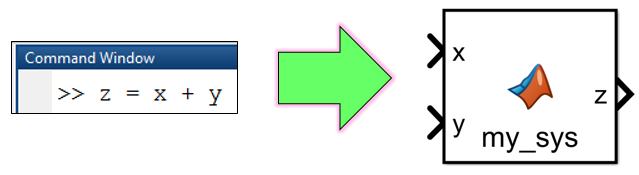

Now create the MATLAB function blocks for Simulink:

tf_i_should_create_SL_block = true;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_lagr';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   
                          
    % Put BOTH equations into one block 
    matlabFunctionBlock( [MODEL_NAME,'/THE_THETA_SYS_DD'], RESULT_TH1, RESULT_TH4, ...
                         'Optimize', false, ...
                         'Outputs', {'theta1_DD', 'theta4_DD'}   );     
end

The Simulink block should look like this:

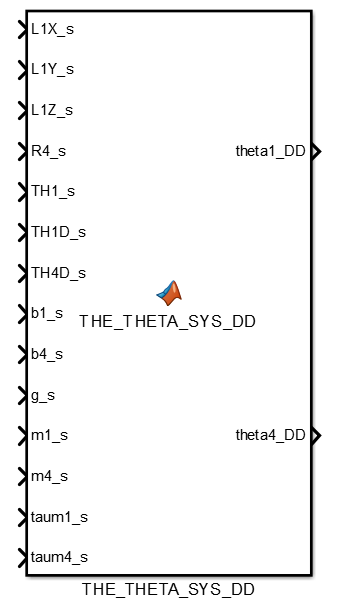

Make the block yellow:

set_param([MODEL_NAME,'/THE_THETA_SYS_DD'],'BackgroundColor', '[0.996078, 1.000000, 0.705882]');       

## A Simulink model of our 2-dof NON-planar manipulator:

Have a look at AND simulate the following Simulink model which contains our hand derived equations of motion:

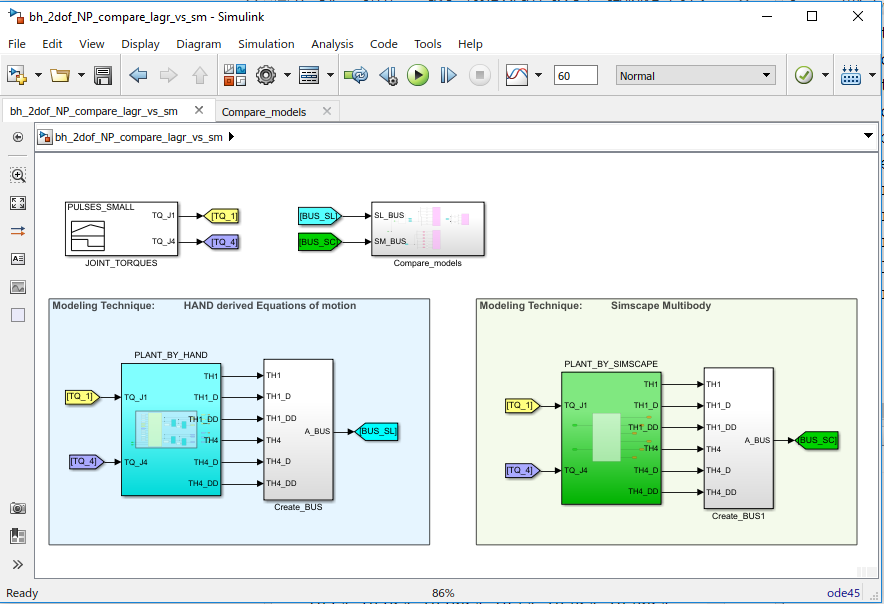

Load some numeric parameters into the MATLAB workspace:

% bh_SIMPARAMS_for_2dof_NP

Open the Simulink file

% open_system('bh_2dof_NP_compare_lagr_vs_sm')

In addition to the hand derived equations of motion, this Simulink file also contains a Simscape Multibody model of the same 2-dof non-planar robot.  We compare the outputs of the 2  different approaches for modelling the robot ... and they are very very similar(as expected).

So ? So what we're going to do today is to learn how to create a Simscape Multibody version of our 2-dof robot, ie: we're going to work though what this means: